# Academic problem

## Introduction

In these tutorial files, you will learn how to use the various modules of Swan in order to generate your own FEM and Topology Optimization simulations. In each tutorial, a single building block will be analyzed, with some examples to make it easier. If you have any questions, feel free to create a new issue in the GitHub repository.

In this tutorial, we will learn how to solve Academic problems in Swan.

## Setting the inputs

An Academic problem is basically a minimization problem where the design variable is a vector of real numbers and the cost and constraints are analytical functions. They are typically used to test optimizers and compare the result with the corresponding analytical solution.

Now, we will define an example. First, we will want to minimize the following cost function in R²:

clear;
close all;
cost.cF = @(x) 0.3*x(1) + x(2);

which gradient is

cost.gF = @(x) [0.3; 1];

Moreover, imagine that we want to fulfill also two additional constraints. We create a cell array where each dimension corresponds to different constraints as follows:

% Constraint nº1
constraint.cF{1} = @(x) 1./x(1) - x(2);

% Gradient of constraint nº1
constraint.gF{1} = @(x) [-1./x(1).^2; -1];

% Constraint nº2
constraint.cF{2} = @(x) x(1)+x(2)-3;

% Gradient of constraint nº2
constraint.gF{2} = @(x) [1; 1];

## Solving the problem

Once the minimization problem is defined, we need also to set the initial guess:

x0 = [1.5;2.25];

And finally, we also define the settings for our optimizer. In this case we will use the fmincon optimizer. Besides, we can define even bound constraints and the maximum number of iterations, all along with the constraint cases (EQUALITY '=0' or INEQUALITY '<=0'):

s.type           = "fmincon";
s.ub             = inf;
s.lb             = -inf;
s.maxIter        = 50;
s.constraintCase = {'INEQUALITY','INEQUALITY'};

We merge all the properties together with the following lines:

cParams.cost         = cost;
cParams.constraint   = constraint;
cParams.initialGuess = x0;
cParams.settings     = s;
cParams.printingPath = true; % Includes an additional path contour plot for two-dimensional design variables
problem              = AcademicProblem(cParams);

And we hence compute our result, being able to visualize the monitoring of the simulation:

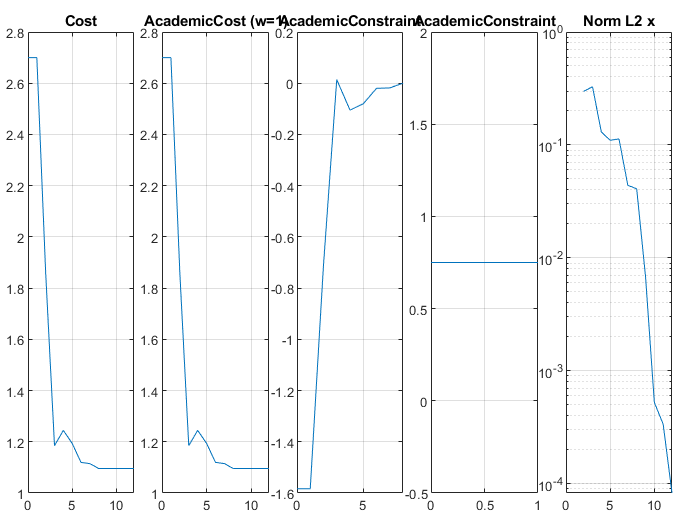


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


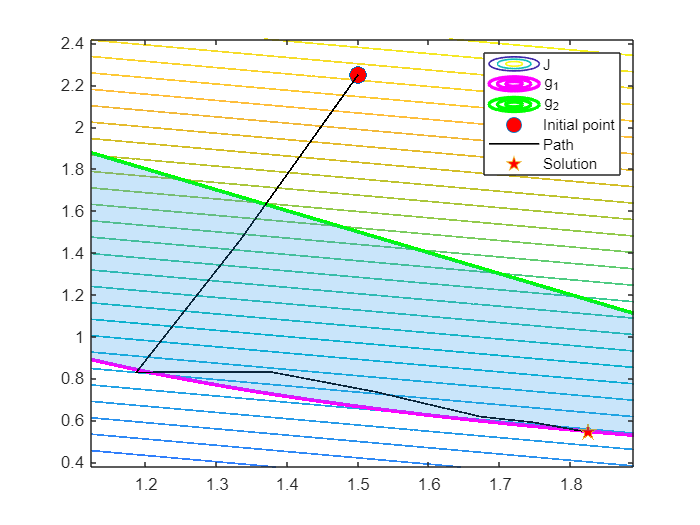

problem.compute();

xStar = problem.result;

## Miss anything?

Feel free to create a new Issue in Swan's GitHub repository with any questions or doubts you may have. We will get back to you as soon as possible!